%% Oppsett
fis = mamfis("Name", "LFR");

fis = addInput(fis, [0, 10000], "Name", "Avvik");
fis = addInput(fis, [-10000, 10000], "Name", "DAvvik");

fis = addOutput(fis, [-26, 26], "Name", "StyreRetning");

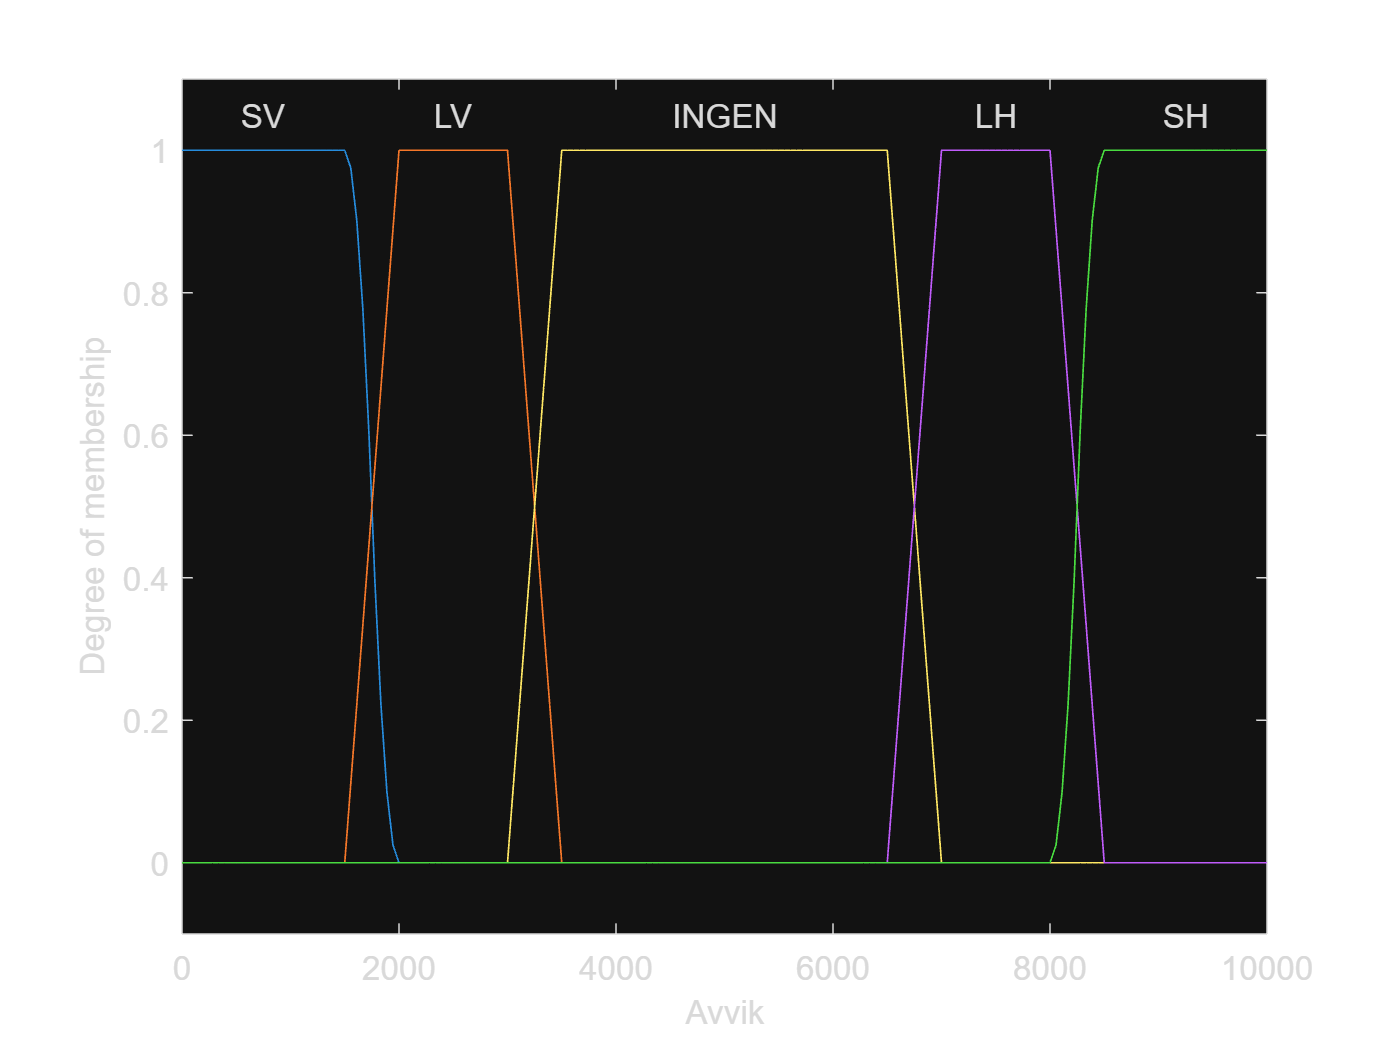

%% Input medlemsfunksjoner

fis = addMF(fis, "Avvik", "zmf", [1500, 2000], "Name", "SV");
fis = addMF(fis, "Avvik", "trapmf", [1500, 2000, 3000, 3500], "Name", "LV");
fis = addMF(fis, "Avvik", "trapmf", [3000, 3500, 6500, 7000], "Name", "INGEN");
fis = addMF(fis, "Avvik", "trapmf", [6500, 7000, 8000, 8500], "Name", "LH");
fis = addMF(fis, "Avvik", "smf", [8000, 8500], "Name", "SH");

fis = addMF(fis, "DAvvik", "zmf", [-6000, -5000], "Name", "SVS");
fis = addMF(fis, "DAvvik", "trapmf", [-6000, -5000, -3000, -2000], "Name", "LVS");
fis = addMF(fis, "DAvvik", "trapmf", [-3000, -2000, 2000, 3000], "Name", "INGEN");
fis = addMF(fis, "DAvvik", "trapmf", [2000, 3000, 5000, 6000], "Name", "LHS");
fis = addMF(fis, "DAvvik", "smf", [5000, 6000], "Name", "SHS");

plotmf(fis, "input", 1);

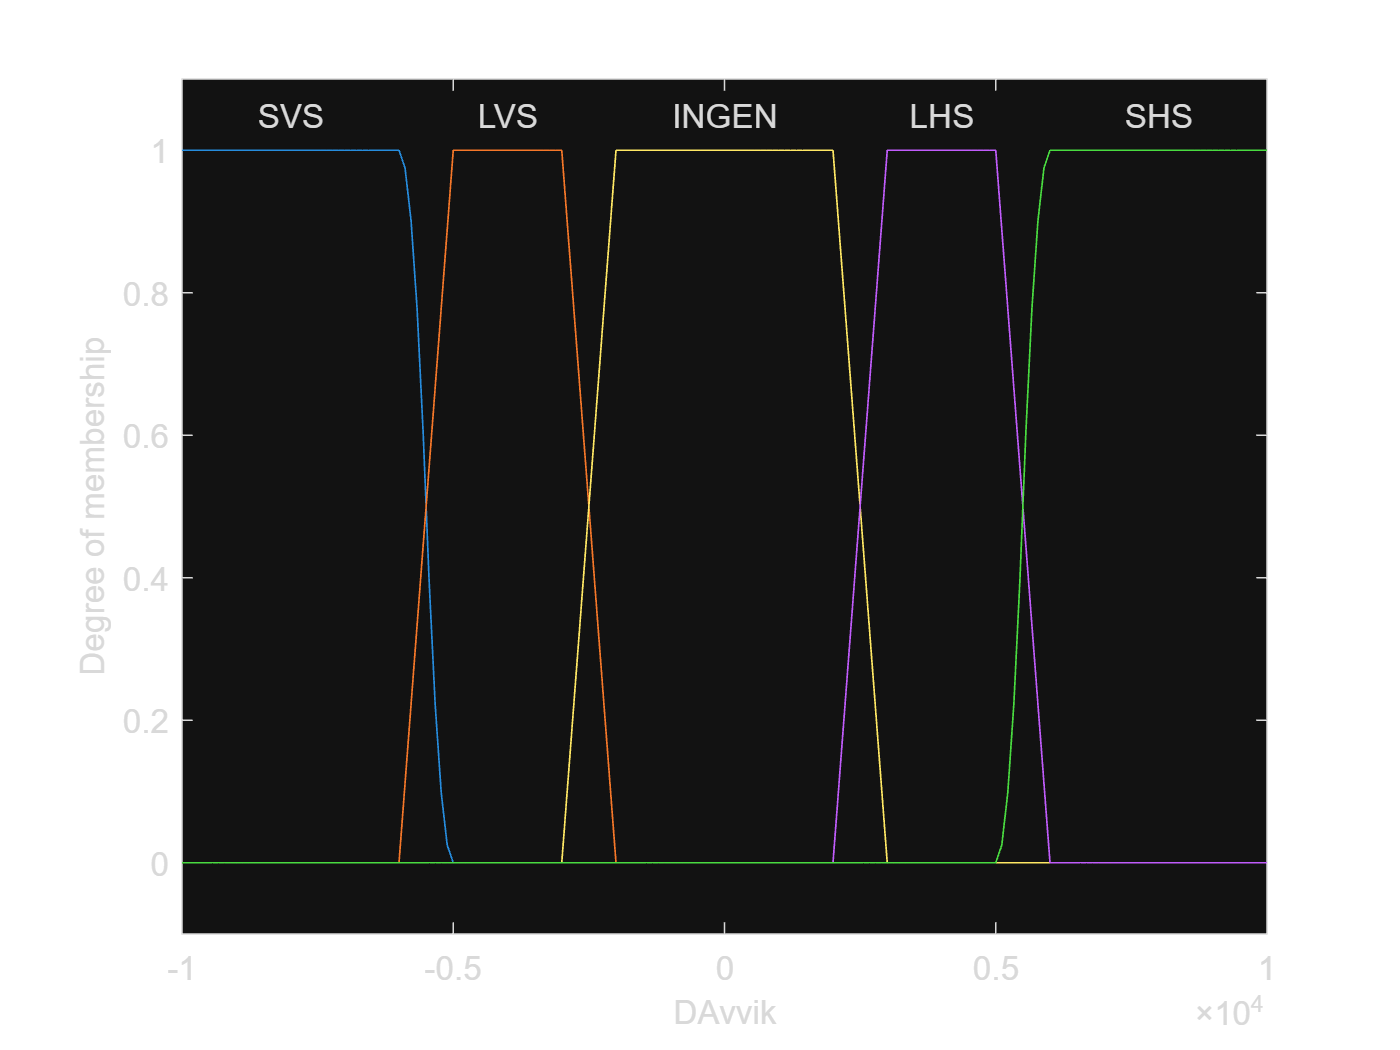

plotmf(fis, "input", 2);

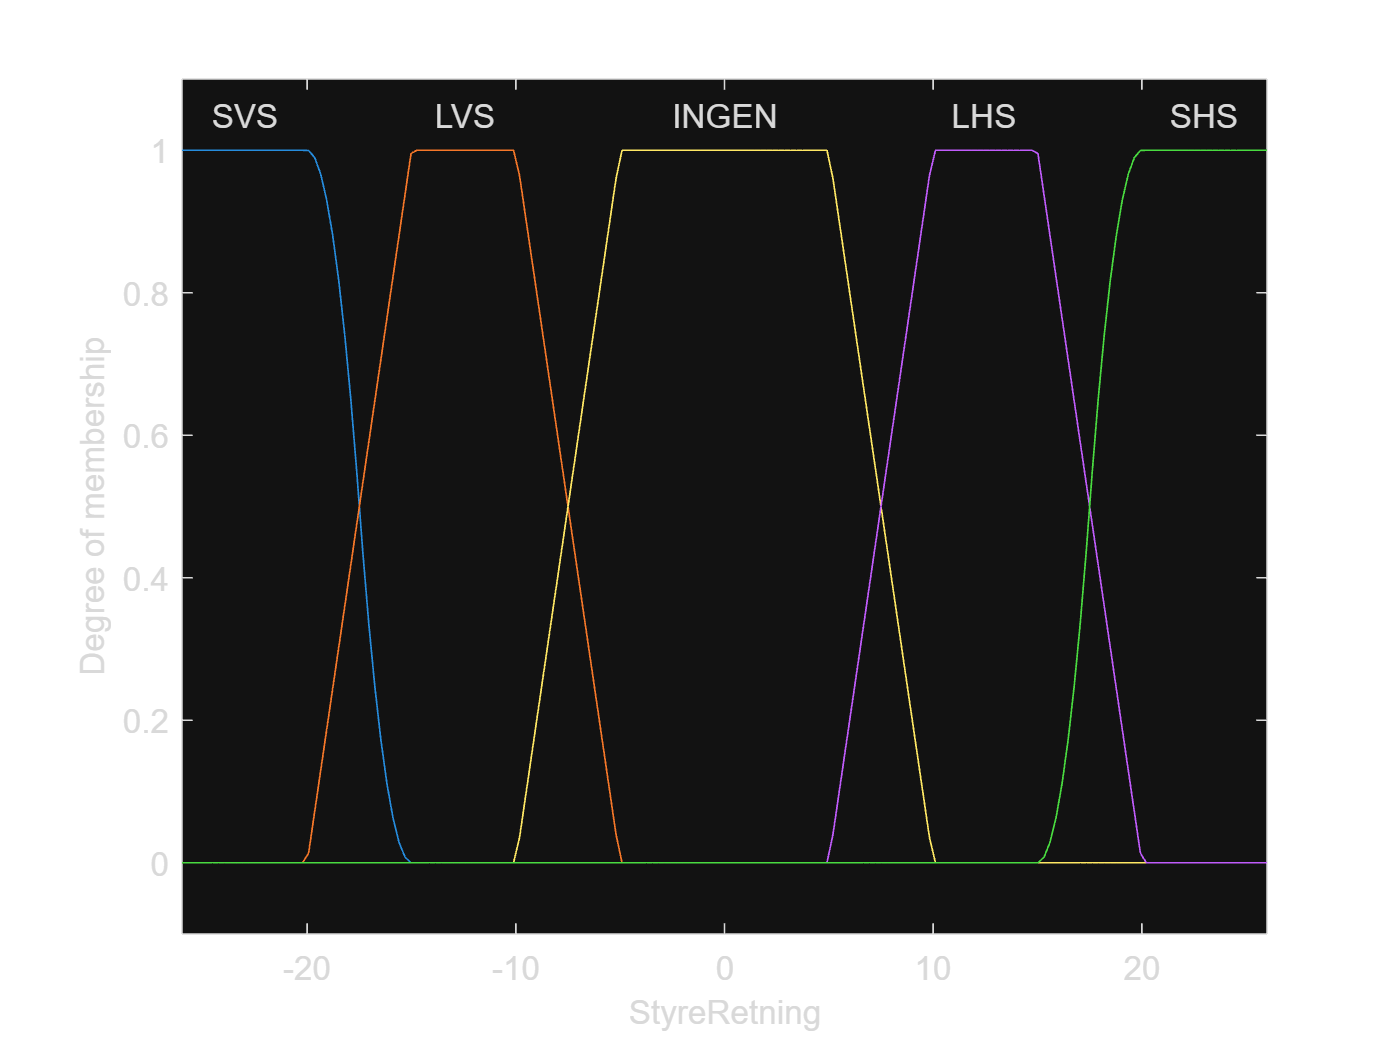

%% Output medlemsfunksjoner

fis = addMF(fis, "StyreRetning", "zmf", [-20, -15], "Name", "SVS");
fis = addMF(fis, "StyreRetning", "trapmf", [-20, -15, -10, -5], "Name", "LVS");
fis = addMF(fis, "StyreRetning", "trapmf", [-10, -5, 5, 10], "Name", "INGEN");
fis = addMF(fis, "StyreRetning", "trapmf", [5, 10, 15, 20], "Name", "LHS");
fis = addMF(fis, "StyreRetning", "smf", [15, 20], "Name", "SHS");

plotmf(fis, "output", 1);

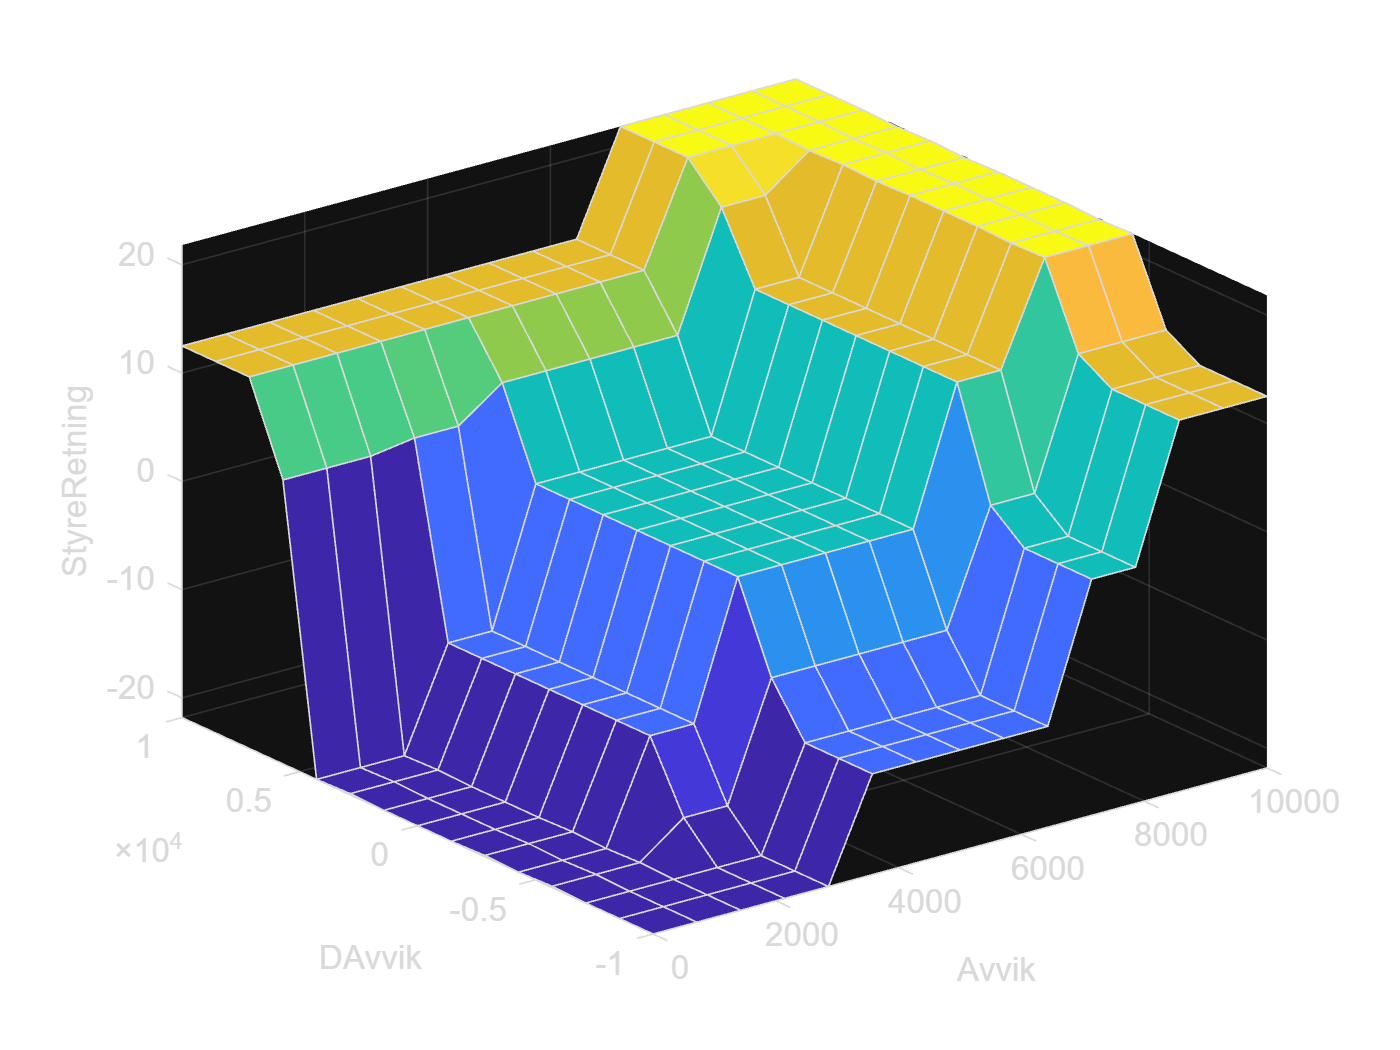

%% Regler

regler = [
    "If Avvik is SV and DAvvik is INGEN then StyreRetning is SVS";
    "If Avvik is LV and DAvvik is INGEN then StyreRetning is LVS";
    "If Avvik is INGEN and DAvvik is INGEN then StyreRetning is INGEN";
    "If Avvik is LH and DAvvik is INGEN then StyreRetning is LHS";
    "If Avvik is SH and DAvvik is INGEN then StyreRetning is SHS";
    
    "If Avvik is SV and DAvvik is LVS then StyreRetning is SVS";
    "If Avvik is LV and DAvvik is LVS then StyreRetning is LVS";
    "If Avvik is INGEN and DAvvik is LVS then StyreRetning is INGEN";
    "If Avvik is LH and DAvvik is LVS then StyreRetning is LHS";
    "If Avvik is SH and DAvvik is LVS then StyreRetning is SHS";
    
    "If Avvik is SV and DAvvik is SVS then StyreRetning is SVS";
    "If Avvik is LV and DAvvik is SVS then StyreRetning is SVS";
    "If Avvik is INGEN and DAvvik is SVS then StyreRetning is LVS";
    "If Avvik is LH and DAvvik is SVS then StyreRetning is INGEN";
    "If Avvik is SH and DAvvik is SVS then StyreRetning is LHS";
    
    "If Avvik is SV and DAvvik is LHS then StyreRetning is SVS";
    "If Avvik is LV and DAvvik is LHS then StyreRetning is LVS";
    "If Avvik is INGEN and DAvvik is LHS then StyreRetning is INGEN";
    "If Avvik is LH and DAvvik is LHS then StyreRetning is LHS";
    "If Avvik is SH and DAvvik is LHS then StyreRetning is SHS";
    
    "If Avvik is SV and DAvvik is SHS then StyreRetning is LHS";
    "If Avvik is LV and DAvvik is SHS then StyreRetning is LHS";
    "If Avvik is INGEN and DAvvik is SHS then StyreRetning is LHS";
    "If Avvik is LH and DAvvik is SHS then StyreRetning is SHS";
    "If Avvik is SH and DAvvik is SHS then StyreRetning is SHS";];

fis = addRule(fis, regler);

gensurf(fis);

Step = 1;
E = 0:Step:100;
CE = -100:Step:100;
N = length(E);
LookUpTableData = zeros(N);
for i=1:length(E)
   for j=1:length(CE)
      % Compute output u for each combination of sample points.
      LookUpTableData(i,j) = evalfis(fis,[E(i) CE(j)]);
   end
end